## Plot Stress Level fitting main results 

% This code was constructed with the use of ChatGPT 
clear; clc; close all;
L = load('results_2PL_Steel.mat');
W = load('results_2PW_Steel.mat');
G = load('results_Gumbel_Steel.mat');
T = load('results_3PW_Steel.mat');

stress_levels = L.stress_levels(:);
num_stress_levels = numel(stress_levels);

% 1. Parameter estimates and B1 life
parameterRows = cell(0,7);

for j = 1:num_stress_levels
    s = stress_levels(j);

    % Lognormal: Location = mu, Scale = sigma, Shape = —
    parameterRows(end+1,:) = {s,'Lognormal','MLE', ...
        L.sigma_estimates(j),NaN,L.mu_estimates(j), ...
        L.B1_lives_2PL(j)};

    parameterRows(end+1,:) = {s,'Lognormal','PPLR', ...
        L.sigma_estimates_PPLR(j),NaN,L.mu_estimates_PPLR(j), ...
        L.B1_lives_PPLR(j)};

    % 2P Weibull: Scale = a, Shape = b, Location = —
    parameterRows(end+1,:) = {s,'2P Weibull','MLE', ...
        W.a_estimates(j),W.b_estimates(j),NaN, ...
        W.B1_lives_2PW(j)};

    parameterRows(end+1,:) = {s,'2P Weibull','PPLR', ...
        W.a_estimates_PPLR(j),W.b_estimates_PPLR(j),NaN, ...
        W.B1_lives_PPLR(j)};

    % Gumbel maximum: Scale = b, Shape = —, Location = a
    parameterRows(end+1,:) = {s,'Gumbel maximum','MLE', ...
        G.b_estimates_MLE(j),NaN,G.a_estimates_MLE(j), ...
        G.B1_lives_Gumbel_MLE(j)};

    parameterRows(end+1,:) = {s,'Gumbel maximum','PPLR', ...
        G.b_estimates_PPLR(j),NaN,G.a_estimates_PPLR(j), ...
        G.B1_lives_PPLR(j)};

    % 3P Weibull MLE: no verifiable parameter estimates
    parameterRows(end+1,:) = {s,'3P Weibull','MLE', ...
        NaN,NaN,NaN,NaN};

    % 3P Weibull PPLR: Scale = a, Shape = b, Location = c
    parameterRows(end+1,:) = {s,'3P Weibull','PPLR', ...
        T.a_estimates(j),T.b_estimates(j),T.c_estimates(j), ...
        T.B1_lives_3PW_PPLR(j)};
end

parameterTable = cell2table(parameterRows, ...
    'VariableNames',{'Stress_MPa','Distribution','Method', ...
    'Scale','Shape','Location','B1_Life_Cycles'});

parameterHeaders = {'Stress (MPa)','Distribution','Method', ...
    'Scale parameter','Shape parameter','Location parameter', ...
    'B1 life (cycles)'};

% Round numerical values to 5 significant figures
for v = {'Stress_MPa','Scale','Shape','Location','B1_Life_Cycles'}
    parameterTable.(v{1}) = ...
        round(parameterTable.(v{1}),5,'significant');
end
disp('PARAMETER ESTIMATES AND B1 LIFE');

PARAMETER ESTIMATES AND B1 LIFE


disp(parameterTable);

    Stress_MPa       Distribution        Method       Scale        Shape      Location     B1_Life_Cycles
    __________    __________________    ________    __________    _______    __________    ______________

       4900       {'Lognormal'     }    {'MLE' }        1.0992        NaN         19.16      1.6244e+07  
       4900       {'Lognormal'     }    {'PPLR'}        1.2031        NaN         19.16      1.2754e+07  
       4900       {'2P Weibull'    }    {'MLE' }    3.5569e+08     1.0359           NaN      4.1918e+06  
       4900       {'2P Weibull'    }    {'PPLR'}    3.5954e+08    0.99007           NaN      3.4506e+06  
       4900       {'Gumbel maximum'}    {'MLE' }    2.1154e+08        NaN    2.0764e+08     -1.1542e+08  
       4900       {'Gumbel maximum'}    {'PPLR'}    3.4326e+08        NaN     1.668e+08     -3.5742e+08  
       4900       {'3P Weibull'    }    {'MLE' }           NaN        NaN           NaN             NaN  
       4900       {'3P Weibull'    }    {'PPL

% Copy report-ready version to clipboard
clipboard('copy',tableToTSV(parameterTable,parameterHeaders));

% 2. Goodness-of-fit table
gofRows = cell(0,6);

for j = 1:num_stress_levels
    s = formatNum(stress_levels(j));

    gofRows(end+1,:) = {s,'Lognormal', ...
        getResult(L,'ad_test',j),getResult(L,'p',j), ...
        getResult(L,'ad_cv',j),decisionFromH(getResult(L,'ad_h',j))};

    gofRows(end+1,:) = {s,'2P Weibull', ...
        getResult(W,'ad_test',j),getResult(W,'p',j), ...
        getResult(W,'ad_cv',j),decisionFromH(getResult(W,'ad_h',j))};

    gofRows(end+1,:) = {s,'Gumbel maximum', ...
        getResult(G,'ad_test',j),getResult(G,'p',j), ...
        getResult(G,'ad_cv',j),decisionFromH(getResult(G,'ad_h',j))};

    gofRows(end+1,:) = {s,'3P Weibull', ...
        formatNum(T.AD_statistic_3PW(j)), ...
        formatNum(T.AD_p_value_3PW(j)), ...
        'Bootstrap calibrated', ...
        decision(T.AD_p_value_3PW(j),0.05)};
end

gofTable = cell2table(gofRows, ...
    'VariableNames',{'Stress_MPa','Distribution','AD_Statistic', ...
    'AD_p_Value','AD_Critical_Value_or_Note','AD_Decision'});

gofHeaders = {'Stress (MPa)','Distribution','AD statistic', ...
    'p-value','Critical value / note','Decision'};

disp('GOODNESS-OF-FIT RESULTS');

GOODNESS-OF-FIT RESULTS


disp(gofTable);

    Stress_MPa       Distribution       AD_Statistic     AD_p_Value      AD_Critical_Value_or_Note       AD_Decision    
    __________    __________________    ____________    _____________    _________________________    __________________

     {'4900'}     {'Lognormal'     }    {'0.26395'}     {'0.67495'  }    {'0.70624'             }     {'Fail to reject'}
     {'4900'}     {'2P Weibull'    }    {'0.23253'}     {'0.82177'  }    {'0.72957'             }     {'Fail to reject'}
     {'4900'}     {'Gumbel maximum'}    {'0.52725'}     {'0.17368'  }    {'0.72957'             }     {'Fail to reject'}
     {'4900'}     {'3P Weibull'    }    {'0.22754'}     {'0.656'    }    {'Bootstrap calibrated'}     {'Fail to reject'}
     {'5500'}     {'Lognormal'     }    {'0.26403'}     {'0.67472'  }    {'0.70624'             }     {'Fail to reject'}
     {'5500'}     {'2P Weibull'    }    {'0.23123'}     {'0.82545'  }    {'0.72957'             }     {'Fail to reject'}
     {'5500'}     {'Gumbel maxi


% Copy report-ready version to clipboard
clipboard('copy',tableToTSV(gofTable,gofHeaders));

%% 3. Tail-fit check table
tailRows = cell(0,6);

for j = 1:num_stress_levels
    s = formatNum(stress_levels(j));

    % Lognormal MLE
    tailRows(end+1,:) = {s,'Lognormal','MLE', ...
        formatNum(L.tail_fit_dF{j}(1)), ...
        formatNum(L.tail_fit_dF{j}(2)), ...
        formatNum(L.tail_fit_dF{j}(3))};

    % Lognormal PPLR
    tailRows(end+1,:) = {s,'Lognormal','PPLR', ...
        formatNum(L.tail_fit_dF_PPLR{j}(1)), ...
        formatNum(L.tail_fit_dF_PPLR{j}(2)), ...
        formatNum(L.tail_fit_dF_PPLR{j}(3))};

    % 2P Weibull MLE
    tailRows(end+1,:) = {s,'2P Weibull','MLE', ...
        formatNum(W.tail_fit_dF_W{j}(1)), ...
        formatNum(W.tail_fit_dF_W{j}(2)), ...
        formatNum(W.tail_fit_dF_W{j}(3))};

    % 2P Weibull PPLR
    tailRows(end+1,:) = {s,'2P Weibull','PPLR', ...
        formatNum(W.tail_fit_dF_PPLR_W{j}(1)), ...
        formatNum(W.tail_fit_dF_PPLR_W{j}(2)), ...
        formatNum(W.tail_fit_dF_PPLR_W{j}(3))};

    % Gumbel maximum MLE
    tailRows(end+1,:) = {s,'Gumbel maximum','MLE', ...
        formatNum(G.tail_fit_dF_G{j}(1)), ...
        formatNum(G.tail_fit_dF_G{j}(2)), ...
        formatNum(G.tail_fit_dF_G{j}(3))};

    % Gumbel maximum PPLR
    tailRows(end+1,:) = {s,'Gumbel maximum','PPLR', ...
        formatNum(G.tail_fit_dF_PPLR_G{j}(1)), ...
        formatNum(G.tail_fit_dF_PPLR_G{j}(2)), ...
        formatNum(G.tail_fit_dF_PPLR_G{j}(3))};

    % 3P Weibull MLE: no MLE results available
    tailRows(end+1,:) = {s,'3P Weibull','MLE', ...
        '—','—','—'};

    % 3P Weibull PPLR
    tailRows(end+1,:) = {s,'3P Weibull','PPLR', ...
        formatNum(T.tail_fit_dF_3PW{j}(1)), ...
        formatNum(T.tail_fit_dF_3PW{j}(2)), ...
        formatNum(T.tail_fit_dF_3PW{j}(3))};
end

tailFitTable = cell2table(tailRows, ...
    'VariableNames',{'Stress_MPa','Distribution','Method', ...
    'Observation_1_dF','Observation_2_dF','Observation_3_dF'});

tailHeaders = {'Stress (MPa)','Distribution','Method', ...
    'Signed CDF difference (1st)', ...
    'Signed CDF difference (2nd)', ...
    'Signed CDF difference (3rd)'};

disp('TAIL-FIT CHECK RESULTS');

TAIL-FIT CHECK RESULTS


disp(tailFitTable);

    Stress_MPa       Distribution        Method     Observation_1_dF    Observation_2_dF    Observation_3_dF
    __________    __________________    ________    ________________    ________________    ________________

     {'4900'}     {'Lognormal'     }    {'MLE' }     {'0.02743'   }      {'0.055568' }       {'0.046554' }  
     {'4900'}     {'Lognormal'     }    {'PPLR'}     {'0.016781'  }      {'0.037546' }       {'0.024721' }  
     {'4900'}     {'2P Weibull'    }    {'MLE' }     {'-0.0070746'}      {'0.022211' }       {'0.031377' }  
     {'4900'}     {'2P Weibull'    }    {'PPLR'}     {'-0.013689' }      {'0.013596' }       {'0.0214'   }  
     {'4900'}     {'Gumbel maximum'}    {'MLE' }     {'-0.042166' }      {'0.0095993'}       {'0.048053' }  
     {'4900'}     {'Gumbel maximum'}    {'PPLR'}     {'-0.16954'  }      {'-0.11606' }       {'-0.072161'}  
     {'4900'}     {'3P Weibull'    }    {'MLE' }     {'—'         }      {'—'        }       {'—'        }  
     {'4900'}     


% Copy report-ready version to clipboard
clipboard('copy',tableToTSV(tailFitTable,tailHeaders));


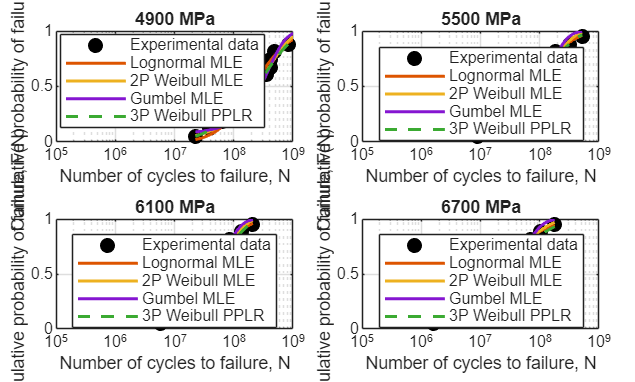

% 4. CDF overlays
figure('Name','CDF comparisons across stress levels');
tiledlayout(2,2,'TileSpacing','compact','Padding','compact');

for j = 1:num_stress_levels
    nexttile;
    hold on; grid on; box on;

    semilogx(L.cdf_life_sorted{j},L.cdf_empirical_F{j},'ko', ...
        'LineStyle','none','MarkerFaceColor','k','LineWidth',1.5, ...
        'DisplayName','Experimental data');
    semilogx(L.cdf_x{j},L.cdf_mle{j},'LineWidth',1.5, ...
        'DisplayName','Lognormal MLE');
    semilogx(W.cdf_x{j},W.cdf_mle{j},'LineWidth',1.5, ...
        'DisplayName','2P Weibull MLE');
    semilogx(G.cdf_x_MLE{j},G.cdf_Gumbel_MLE{j},'LineWidth',1.5, ...
        'DisplayName','Gumbel MLE');
    semilogx(T.cdf_x{j},T.cdf_3PW_PPLR{j},'--','LineWidth',1.5, ...
        'DisplayName','3P Weibull PPLR');

    set(gca,'XScale','log');
    xticks(10.^(5:9));
    xticklabels({'10^5','10^6','10^7','10^8','10^9'});
    xlim([1e5 1e9]);

    xlabel('Number of cycles to failure, N');
    ylabel('Cumulative probability of failure, F(N)');
    title(sprintf('%g MPa',stress_levels(j)));
    ylim([0 1]);

    legend('Location','best','FontSize',8);
    hold off;
end


%4. B1 S-N comparison

data = readtable("G20CrNi2Mo Bearing Steel Data_Zhao.xlsx");

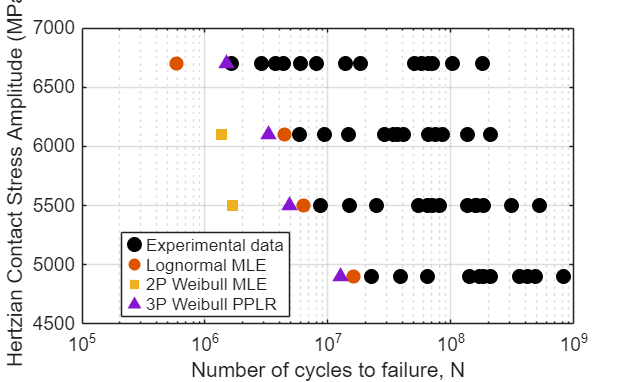


figure('Name','B1 S-N comparison');
hold on; grid on; box on;

% Experimental data
semilogx(data.NumberOfCycles,data.ContactStressAmplitude_MPa_, ...
    'ko','LineStyle','none','MarkerFaceColor','k','LineWidth',1.5, ...
    'DisplayName','Experimental data');

% B1 predictions
scatter(L.B1_lives_2PL,stress_levels,50,'o','filled', ...
    'DisplayName','Lognormal MLE');
scatter(W.B1_lives_2PW,stress_levels,50,'s','filled', ...
    'DisplayName','2P Weibull MLE');
%scatter(G.B1_lives_Gumbel_MLE,stress_levels,50,'d','filled', ...
    %'DisplayName','Gumbel MLE');
scatter(T.B1_lives_3PW_PPLR,stress_levels,50,'^','filled', ...
    'DisplayName','3P Weibull PPLR');

set(gca,'XScale','log');
xticks(10.^(5:9));
xticklabels({'10^5','10^6','10^7','10^8','10^9'});
xlim([1e5 1e9]);

xlabel('Number of cycles to failure, N');
ylabel('Hertzian Contact Stress Amplitude (MPa)');
%title('Experimental S-N data and B1 predictions');
legend('Location','best');
hold off;

% 5. Copy tables to Word
% Local helper functions
function out = formatNum(x)
    if isnumeric(x) && isscalar(x) && isfinite(x)
        out = sprintf('%.5g',x);
    else
        out = 'Not available';
    end
end

function out = getResult(S,field,j)
    if ~isfield(S,field)
        out = 'Not saved';
        return;
    end

    value = S.(field);

    if iscell(value)
        value = value{j};
    elseif numel(value) >= j
        value = value(j);
    else
        out = 'Not available';
        return;
    end

    out = char(string(value));
end

function out = decision(pValue,alpha)
    if pValue >= alpha
        out = 'Fail to reject';
    else
        out = 'Reject';
    end
end

% for conversting text to tab separated values
function txt = tableToTSV(T, headers)

    C = table2cell(T);
    [nRows,nCols] = size(C);

    output = cell(nRows+1,nCols);
    output(1,:) = headers;

    for r = 1:nRows
        for c = 1:nCols
            value = C{r,c};

            if isnumeric(value) && isscalar(value)
                if isnan(value) || isinf(value)
                    output{r+1,c} = char(8212);
                else
                    output{r+1,c} = sprintf('%.5g',value);
                end

            elseif isstring(value)
                if ismissing(value)
                    output{r+1,c} = char(8212);
                else
                    output{r+1,c} = char(value);
                end

            elseif ischar(value)
                if isempty(value)
                    output{r+1,c} = char(8212);
                else
                    output{r+1,c} = value;
                end

            else
                output{r+1,c} = char(8212);
            end
        end
    end

    lines = cell(nRows+1,1);
    for r = 1:nRows+1
        lines{r} = strjoin(output(r,:),sprintf('\t'));
    end

    txt = strjoin(lines,sprintf('\n'));
end

% for hypothesis decison output
function out = decisionFromH(h)
    if ischar(h) || isstring(h)
        h = str2double(h);
    end

    if isempty(h) || ~isscalar(h) || ...
            ~(isnumeric(h) || islogical(h)) || ...
            ~isfinite(h) || ~ismember(h,[0 1])
        out = 'Not available';
    elseif h == 0
        out = 'Fail to reject';
    else
        out = 'Reject';
    end
end